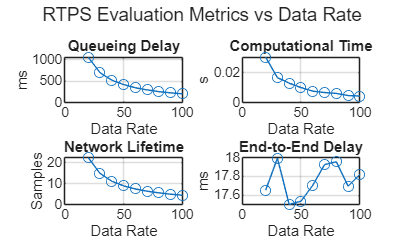


% RTPS Protocol Simulation for WBASN with OLQS-style Traffic Prioritization and Binary Data Marking
clc; clear;

%% Network Parameters
areaSize = 200; % cm (2m x 2m)
numRelays = 12;
numSources = 8;
numSink = 1;
numNodes = numRelays + numSources + numSink;
range = 50; % cm
initialEnergy = 50;
energyThreshold = 0.2 * initialEnergy;
packetSize = 1500; % bytes
dataRates = 20:10:100;
simTime = 1000;
queueDelayBase = 5; queueVar = 10;

%% Node Initialization
roles = [repmat("Relay", 1, numRelays), repmat("Source", 1, numSources), "Sink"];
positions = rand(numNodes, 2) * areaSize;
energyOriginal = initialEnergy * ones(numNodes, 1);
sinkID = numNodes;

%% Import Sensor Data
sensorData = readmatrix('DATA.csv');
if size(sensorData,2) ~= numSources
    error('Expected 8 columns of sensor data for 8 source nodes.');
end

%% Metrics Initialization
energyPerSource = zeros(length(dataRates), numSources);
metrics = zeros(length(dataRates), 4); % QueueDelay, CompTime, Lifetime, E2EDelay

%% Simulation Loop
for drIdx = 1:length(dataRates)
    dataRate = dataRates(drIdx);
    energy = energyOriginal;
    nodeDead = false(numNodes, 1);

    totalQueueDelay = 0;
    queueFluctuation = 1 + 0.3 * sin(1:size(sensorData,1));
    totalE2EDelay = zeros(size(sensorData,1), 1);
    networkLifetime = 0;
    tStart = tic;

    for t = 1:size(sensorData,1)
        roundE2EDelay = 0; validCount = 0;
        for s = 1:numSources
            srcID = numRelays + s;
            if nodeDead(srcID), continue; end

            % OLQS-style criticality rule
            HR = sensorData(t,1); BP = sensorData(t,2); BT = sensorData(t,3);
            RR = sensorData(t,4); BS = sensorData(t,5);

            switch s
                case 1, isCritical = (HR < 50 || HR > 120);
                case 2, isCritical = (BP >= 180 || BP <= 90);
                case 3, isCritical = (BT >= 40 || BT < 35);
                case 4, isCritical = (RR < 8 || RR > 30);
                case 5, isCritical = (BS < 54 || BS >= 300);
                otherwise, isCritical = false;
            end

            % Binary data marking
            if isCritical
                binaryData = [0 1]; % Critical data
                distToSink = norm(positions(srcID,:) - positions(sinkID,:));
                delay = rand() * 100 + distToSink * 0.1;
                roundE2EDelay = roundE2EDelay + delay;
                energy(srcID) = energy(srcID) - 0.1;
                if energy(srcID) < energyThreshold
                    nodeDead(srcID) = true;
                end
            else
                binaryData = [0 0]; % Normal data
                dists = vecnorm(positions - positions(srcID,:), 2, 2);
                eligible = find(dists <= range & roles == "Relay" & ~nodeDead);
                if isempty(eligible), continue; end

                DelayAll = rand(length(eligible),1)*100;
                SINR = 10 + rand(length(eligible),1)*5;
                SNR = SINR + rand(length(eligible),1)*5;
                interferenceRatio = SINR ./ SNR;
                LQI = interferenceRatio + DelayAll;

                RLTD_Cost_Sub = 0.5 * LQI + 0.5 * DelayAll;
                [~, bestIdx] = min(RLTD_Cost_Sub);
                nextHop = eligible(bestIdx);

                if nextHop > length(energy), continue; end

                delay = DelayAll(bestIdx) + rand()*queueVar;
                roundE2EDelay = roundE2EDelay + delay;

                energy(srcID) = energy(srcID) - 0.05;
                energy(nextHop) = energy(nextHop) - 0.05;

                if energy(srcID) < energyThreshold, nodeDead(srcID) = true; end
                if energy(nextHop) < energyThreshold, nodeDead(nextHop) = true; end
            end

            if networkLifetime == 0 && any(energy < energyThreshold)
                networkLifetime = t;
            end

            totalQueueDelay = totalQueueDelay + queueDelayBase;
            validCount = validCount + 1;
        end

        if validCount > 0
            totalE2EDelay(t) = roundE2EDelay / validCount;
        else
            totalE2EDelay(t) = NaN;
        end
    end

    tComp = toc(tStart) / dataRate;
    metrics(drIdx,:) = [
        totalQueueDelay/dataRate, ...
        tComp, ...
        networkLifetime/dataRate, ...
        mean(totalE2EDelay(~isnan(totalE2EDelay)))
    ];

    for s = 1:numSources
        srcID = numRelays + s;
        if srcID <= length(energy)
            energyPerSource(drIdx,s) = initialEnergy - energy(srcID);
        end
    end
end

%% Save Metrics
writematrix([dataRates(:), metrics(:,1)], 'Queueing_Delay_RTPS.csv');
writematrix([dataRates(:), metrics(:,2)], 'Computational_Time_RTPS.csv');
writematrix([dataRates(:), metrics(:,3)], 'Network_Lifetime_RTPS.csv');
writematrix([dataRates(:), metrics(:,4)], 'End_to_End_Delay_RTPS.csv');
writematrix(energyPerSource, 'Energy_Source_Node_RTPS.csv');

%% Plot Results
figure;
subplot(2,2,1); plot(dataRates, metrics(:,1), '-o'); title('Queueing Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
subplot(2,2,2); plot(dataRates, metrics(:,2), '-o'); title('Computational Time'); xlabel('Data Rate'); ylabel('s'); grid on;
subplot(2,2,3); plot(dataRates, metrics(:,3), '-o'); title('Network Lifetime'); xlabel('Data Rate'); ylabel('Samples'); grid on;
subplot(2,2,4); plot(dataRates, metrics(:,4), '-o'); title('End-to-End Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
sgtitle('RTPS Evaluation Metrics vs Data Rate');

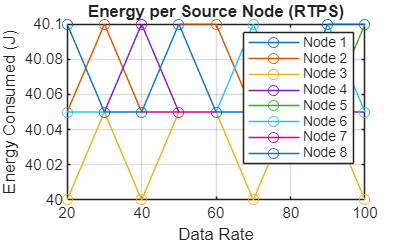


figure;
for s = 1:numSources
    plot(dataRates, energyPerSource(:,s), '-o', 'DisplayName', ['Node ' num2str(s)]); hold on;
end
xlabel('Data Rate'); ylabel('Energy Consumed (J)');
title('Energy per Source Node (RTPS)'); grid on; legend show;